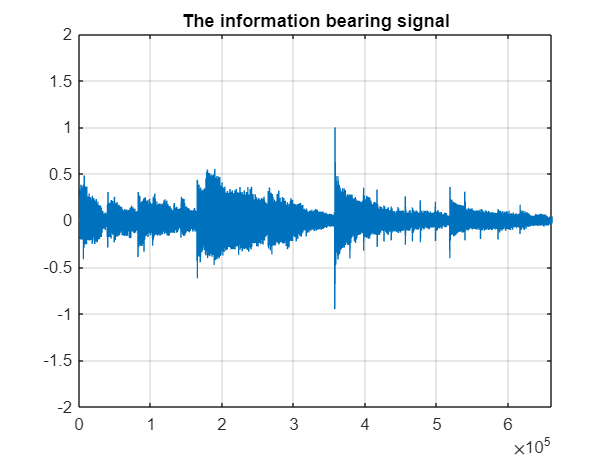

% signal = sin(2*pi*0.055*(0:1000-1)');
% signalSource = dsp.SignalSource(signal,'SamplesPerFrame',100,...
%     'SignalEndAction','Cyclic repetition');

[signal, Fs] = audioread('guitartune.wav');
% signalSource = dsp.SignalSource(signal,'SamplesPerFrame',100,...
%     'SignalEndAction','Cyclic repetition');
plot(0:length(signal)-1,signal);
grid; axis([0 length(signal)-1 -2 2]);
title('The information bearing signal');

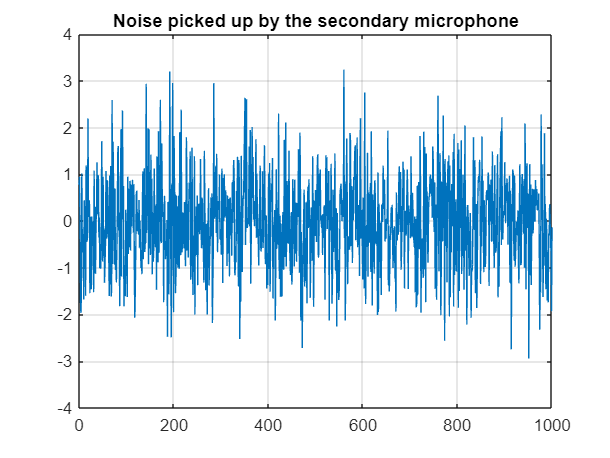

nvar  = 1.0;                  % Noise variance
noise = randn(length(signal),1)*nvar;   % White noise
% noiseSource = dsp.SignalSource(noise,'SamplesPerFrame',100,...
%     'SignalEndAction','Cyclic repetition');
plot(0:length(signal)-1,noise);
title('Noise picked up by the secondary microphone');
grid; axis([0 1000 -4 4]);

lp = dsp.FIRFilter('Numerator',fir1(31,0.5));% Low pass FIR filter

M      = 32;                 % Filter order
delta  = 0.1;                % Initial input covariance estimate
P0     = (1/delta)*eye(M,M); % Initial setting for the P matrix
rlsfilt = dsp.RLSFilter(M,'InitialInverseCovariance',P0);

scope = timescope('TimeSpan',1000,'YLimits',[-2,2], ...
	                  'TimeSpanOverrunAction','Scroll');
for k = 1:10
    %n = noiseSource(); % Noise
    %s = signalSource();
    d = lp(noise) + signal;
    [y,e]  = rlsfilt(noise,d);
    scope([y,e]);
end
release(scope);

H  = abs(freqz(rlsfilt.Coefficients,1,64));
H1 = abs(freqz(lp.Numerator,1,64));

wf = linspace(0,1,64);

plot(wf,H,wf,H1);
xlabel('Normalized Frequency  (\times\pi rad/sample)');
ylabel('Magnitude');
legend('Adaptive Filter Response','Required Filter Response');
grid;
axis([0 1 0 2]);



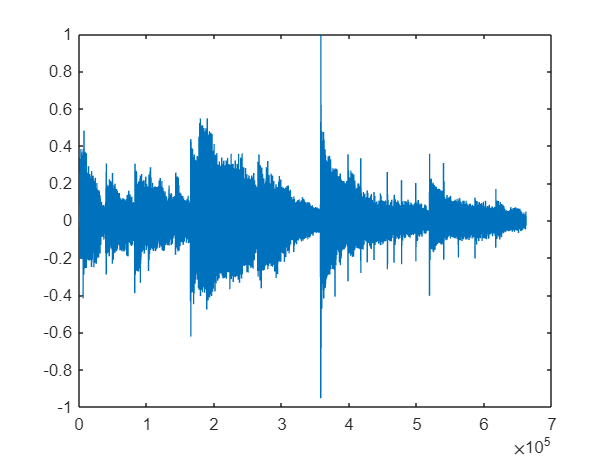

plot(0:length(signal)-1,signal)

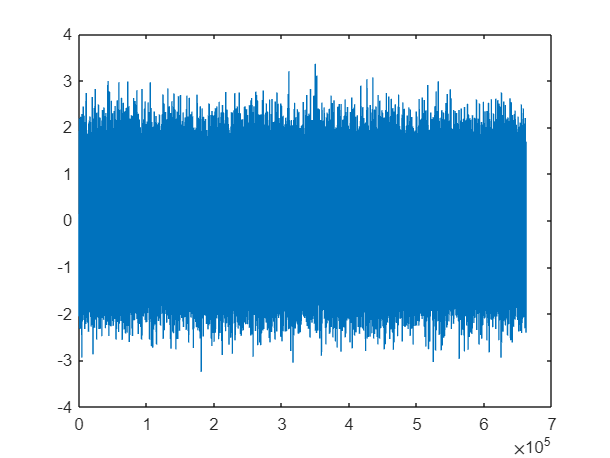

plot(0:length(y)-1,y) % guessed noise

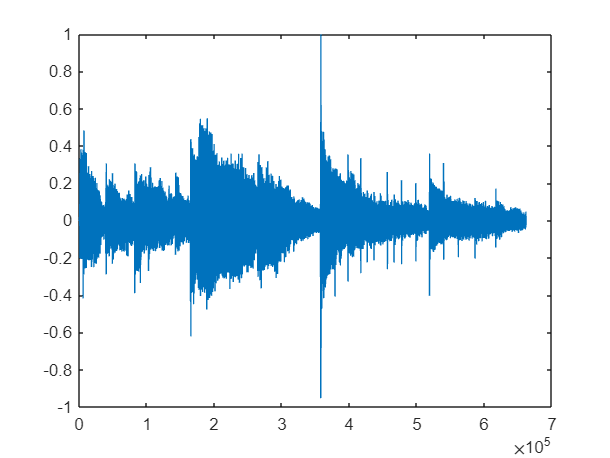

plot(0:length(e)-1,e) % estimated signal

sound(e,Fs)